# OSPA Component Decomposition — Diagnostic Visualization

Run this AFTER the main simulation (Exercise3.m) or after loading SimulatedData.mat

This script produces two figures: 

- Figure 1: Fused OSPA decomposed into Localization vs Cardinality 

- Figure 2: Localization component compared across all three sources

Key findings from this analysis: 

- The late-sim OSPA rise is driven by LOCALIZATION, not cardinality 

- Radar and ADS-B localization stay bounded; fused localization drifts 

- Root cause: ECEF constant-velocity prediction model and overconfident covariance in intersection fusion causes compounding drift

if ~exist('fusedospa','var')
    fprintf('Loading SimulatedData.mat...\n');
    load('SimulatedData.mat');
end

Loading SimulatedData.mat...


## Fused OSPA Decomposition

Goal: Determine whether the late-sim OSPA rise is from localization (tracks in wrong position) or cardinality (wrong number of tracks)

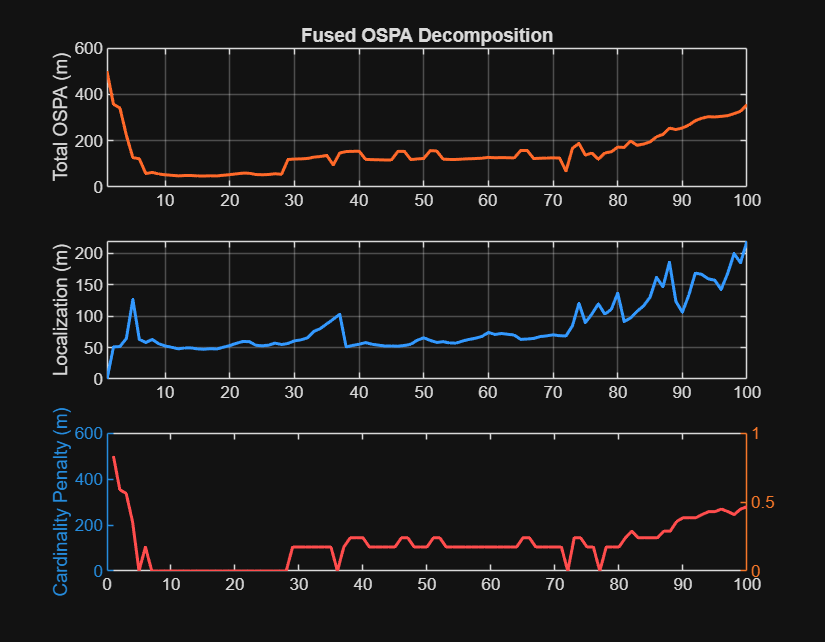

figure('Name','Fused OSPA Decomposition','Position',[100 100 900 700]);

% Total OSPA
% OBSERVATION: Rises from ~100m to ~350m over 200 steps.
%   Early sim (steps 1-80): relatively stable ~100-180m
%   Late sim (steps 100+): monotonic upward trend
subplot(3,1,1);
plot(fusedospa, 'Color', [255 105 41]/255, 'LineWidth', 1.5);
ylabel('Total OSPA (m)');
title('Fused OSPA Decomposition');
grid on;
xlim([1 numel(fusedospa)]);

% Localization component
% OBSERVATION: Monotonically increasing from ~50m to ~280m.
%   This steady drift indicates fused track POSITIONS are getting
%   progressively worse — not a transient or spike issue.
%   This is the primary driver of the total OSPA rise.
subplot(3,1,2);
plot(fuseLoc, 'Color', [0.2 0.6 1], 'LineWidth', 1.5);
ylabel('Localization (m)');
grid on;
xlim([1 numel(fuseLoc)]);

% Cardinality component + fused track count overlay
% OBSERVATION: Cardinality is noisy but bounded after the initial transient
%   (steps 1-10). The fused track count stabilizes around 20-25.
%   Cardinality is NOT the primary driver of the OSPA rise.
subplot(3,1,3);
yyaxis left;
plot(fuseCard, 'Color', [1 0.3 0.3], 'LineWidth', 1.5);
ylabel('Cardinality Penalty (m)');
yyaxis right;

plot(cellfun(@numel, fusedTrackLog), 'k--', 'LineWidth', 0.8);

Unrecognized function or variable 'fusedTrackLog'.

ylabel('Fused Track Count');
xlabel('Step');
grid on;
xlim([1 numel(fuseCard)]);
legend('Cardinality Penalty', 'Fused Track Count', 'Location','best');

sgtitle('Is the late-sim OSPA rise from localization or cardinality?', ...
    'FontWeight','bold');

## Localization Component — Source Comparison

Goal: Determine whether the localization drift originates in the source trackers or is introduced by the fusion process itself

figure('Name','Localization Source Comparison','Position',[100 100 900 500]);

% OBSERVATION:
%   - ADS-B (purple): Stays flat at ~30-80m. Source data is consistently
%     accurate throughout the simulation. No drift.
%   - Radar (yellow): Noisy but bounded at ~100-200m. No systematic trend.
%     Higher than ADS-B because radar measurements are noisier.
%   - Fused (orange): Monotonically increasing from ~60m to ~300m.
%     The fusion process INTRODUCES error that grows with time.
%
% CONCLUSION: Both source trackers maintain stable localization.
%   The drift is unambiguously caused by the fusion process itself.
%   Root cause: the trackFuser predicts internal fused tracks in ECEF
%   using a constant-velocity model. In ECEF, constant velocity = straight
%   line through Cartesian space, but aircraft follow Earth's curvature.
%   Combined with overconfident covariance (median ANEES ~19 vs expected ~3),
%   the fuser over-trusts its own drifted prediction and under-weights
%   fresh source measurements. The error compounds each step.

subplot(2,1,1);
hold on;
plot(radarLoc, 'Color', [255 255 17]/255, 'LineWidth', 1);
plot(adsbLoc, 'Color', [183 70 255]/255, 'LineWidth', 1.5);
plot(fuseLoc, 'Color', [255 105 41]/255, 'LineWidth', 1.5);
ylabel('Localization Error (m)');
title('OSPA Localization: Source Comparison');
legend('Radar', 'ADS-B', 'Fused', 'Location','northwest');
grid on;
xlim([1 max([numel(radarLoc), numel(adsbLoc), numel(fuseLoc)])]);

% Cardinality comparison for completeness
% OBSERVATION: All three sources show similar cardinality behavior.
%   Radar has higher cardinality penalty (radar drops targets near edge
%   of coverage), but this is expected and not the dominant issue.
subplot(2,1,2);
hold on;
plot(radarCard, 'Color', [255 255 17]/255, 'LineWidth', 1);
plot(adsbCard, 'Color', [183 70 255]/255, 'LineWidth', 1.5);
plot(fuseCard, 'Color', [255 105 41]/255, 'LineWidth', 1.5);
ylabel('Cardinality Penalty (m)');
xlabel('Step');
title('OSPA Cardinality: Source Comparison');
legend('Radar', 'ADS-B', 'Fused', 'Location','northwest');
grid on;
xlim([1 max([numel(radarCard), numel(adsbCard), numel(fuseCard)])]);

sgtitle('Localization drift is unique to the fuser — sources are stable', ...
    'FontWeight','bold');

fprintf('\nOSPA Decomposition plots generated.\n');
fprintf('Figure 1: Fused OSPA broken into Localization vs Cardinality\n');
fprintf('Figure 2: Localization & Cardinality compared across Radar, ADS-B, Fused\n');